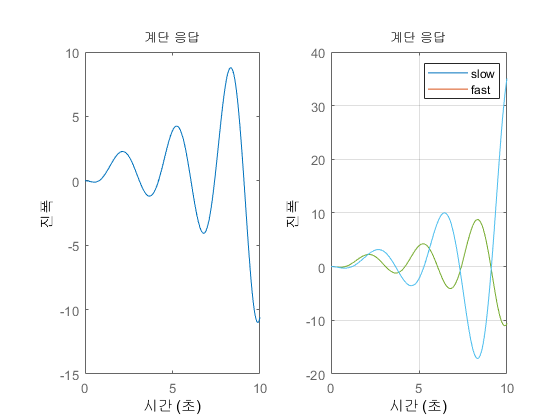

clear, hold off

syms s t % t1 t2 K;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.



K = 1; t1 = 2; t2 = 0.5;
ts = 0.6; tf = 1;

t = ts;

P = -K*(t1*s+1)*(t*s-2)/(t2*s+1)/(t*s+2)

P =
 
  -1.2 s^2 + 3.4 s + 2
  --------------------
  0.3 s^2 + 1.6 s + 2
 
연속시간 전달 함수입니다.



E = -10/(s+10);
A = -(s+6)/s/(s^2+3*s+6);
G = P*E*A

G =
 
                -12 s^3 - 38 s^2 + 224 s + 120
  ----------------------------------------------------------
  0.3 s^6 + 5.5 s^5 + 33.6 s^4 + 101.6 s^3 + 168 s^2 + 120 s
 
연속시간 전달 함수입니다.



T1 = G/(1+G)

T1 =
 
                                                                                        
  -3.6 s^9 - 77.4 s^8 - 545 s^7 - 1228 s^6 + 2310 s^5 + 1.897e04 s^4 + 45264 s^3        
                                                                                        
                                                                   + 47040 s^2 + 14400 s
                                                                                        
  --------------------------------------------------------------------------------------
                                                                                        
  0.09 s^12 + 3.3 s^11 + 50.41 s^10 + 427 s^9 + 2270 s^8 + 8203 s^7 + 2.17e04 s^6       
                                                                                        
                         + 4.451e04 s^5 + 7.157e04 s^4 + 85584 s^3 + 61440 s^2 + 14400 s
                                                                                        
 
연속시간 전달 함수입니

t = tf;

P = -K*(t1*s+1)*(t*s-2)/(t2*s+1)/(t*s+2)

P =
 
  -2 s^2 + 3 s + 2
  -----------------
  0.5 s^2 + 2 s + 2
 
연속시간 전달 함수입니다.



E = -10/(s+10)

E =
 
   -10
  ------
  s + 10
 
연속시간 전달 함수입니다.



A = -(s+6)/s/(s^2+3*s+6)

A =
 
       -s - 6
  -----------------
  s^3 + 3 s^2 + 6 s
 
연속시간 전달 함수입니다.



G = P*E*A

G =
 
              -20 s^3 - 90 s^2 + 200 s + 120
  ------------------------------------------------------
  0.5 s^6 + 8.5 s^5 + 46 s^4 + 128 s^3 + 192 s^2 + 120 s
 
연속시간 전달 함수입니다.



T2 = G/(1+G)

T2 =
 
                                                                                         
  -10 s^9 - 215 s^8 - 1585 s^7 - 4940 s^6 - 5140 s^5 + 11440 s^4 + 42960 s^3 + 47040 s^2 
                                                                                         
                                                                               + 14400 s 
                                                                                         
  ---------------------------------------------------------------------------------------
                                                                                        
  0.25 s^12 + 8.5 s^11 + 118.3 s^10 + 900 s^9 + 4269 s^8 + 13575 s^7 + 31148 s^6        
                                                                                        
                               + 55052 s^5 + 79024 s^4 + 89040 s^3 + 61440 s^2 + 14400 s
                                                                                        
 
연속시간 전

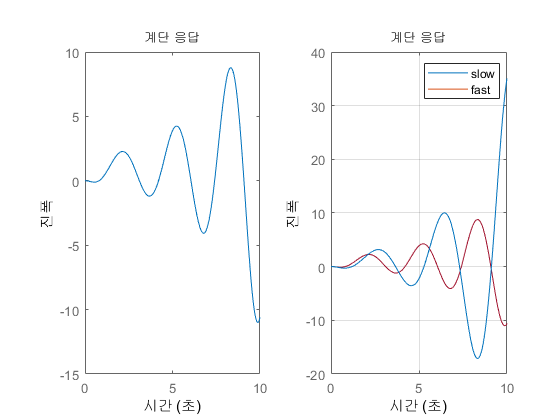

hold on
step(T1, 10), step(T2, 10)
grid on
legend('slow', 'fast')